
=== ADC Signal Analysis Results ===
Channel | Amplitude | Init Phase (deg) | Init Phase (rad)
--------|-----------|------------------|------------------
  ADC0  |     17.04 |       147.49     |       2.5742
  ADC1  |     19.13 |       160.84     |       2.8073
  ADC2  |     16.00 |        38.58     |       0.6733
  ADC3  |     17.28 |       -77.27     |      -1.3485
  ADC4  |     18.10 |       -44.83     |      -0.7824
  ADC5  |     17.01 |        52.09     |       0.9092
  ADC6  |     25.37 |        76.28     |       1.3313
  ADC7  |     16.91 |      -113.11     |      -1.9742



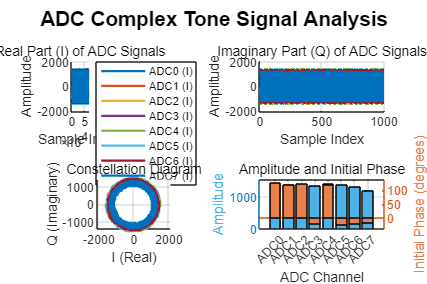

Signal Statistics:
Average amplitude: 18.36
Amplitude std dev: 2.98
Phase spread: 273.96 degrees


[init_phase, amp] = analyzeAdcSignals(adcData, true);

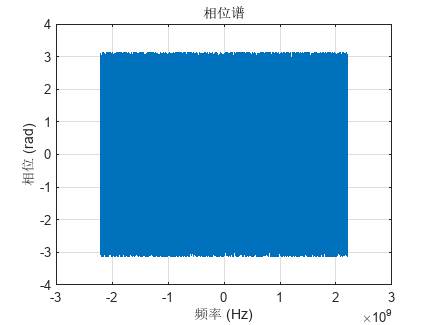

% F:\Vivado\ZU47DR_MTS_test
% F = fftshift(fft(adcData.adc1));
% adc_sample_rate = 4.4237e9;
% decimation_rate = 1;
% fs = adc_sample_rate/decimation_rate;
% 假设 adcData.adc1 是一个 1x65536 的复信号
% 如果数据是行向量，转换为列向量以便处理
signal = adcData.adc5(:);

% 参数设置
fs = 4.42368e9; % 采样频率（Hz）
N = length(signal); % 信号长度（65536）

% 计算FFT（使用汉宁窗减少频谱泄漏）
window = hann(N);
windowed_signal = signal .* window;
spectrum = fft(windowed_signal);

% 计算幅度谱（转换为dB）
magnitude = abs(spectrum);
magnitude_dB = 20*log10(magnitude);

% 计算频率轴（从 -fs/2 到 fs/2）
freq_axis = (-N/2:N/2-1) * (fs / N);

% 移动零频率到中心
magnitude_dB_shifted = fftshift(magnitude_dB);

% 绘制频谱
figure;
plot(freq_axis, magnitude_dB_shifted);
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
title('信号频谱');
grid on;

% 设置x轴范围以关注主要频率成分（例如，从 -fs/4 到 fs/4）
% xlim([-fs/4, fs/4]); % 可根据需要调整范围

% 可选：绘制相位谱
phase = angle(spectrum);
phase_shifted = fftshift(phase);
figure;
plot(freq_axis, phase_shifted);
xlabel('频率 (Hz)');
ylabel('相位 (rad)');
title('相位谱');
grid on;

% xlim([-fs/4, fs/4]);

function [init_phase, amp] = analyzeAdcSignals(adc_data, plot_enable)
    % analyzeAdcSignals - Analyze complex tone signals from ADC data
    % 
    % This function calculates the initial phase and amplitude of complex
    % tone signals from each ADC channel
    %
    % Inputs:
    %   adc_data    - Structure with fields adc0, adc1, ..., adc7
    %                 Each field contains complex baseband IQ data
    %   plot_enable - (optional) Boolean flag to enable plotting
    %                 Default: false
    %
    % Outputs:
    %   init_phase  - 1x8 vector of initial phases (radians)
    %   amp         - 1x8 vector of amplitudes
    %
    % Usage:
    %   [phase, amplitude] = analyzeAdcSignals(board1_adc_data);
    %   [phase, amplitude] = analyzeAdcSignals(board1_adc_data, true);
    
    if nargin < 2
        plot_enable = false;
    end
    
    % Initialize output vectors
    init_phase = zeros(1, 8);
    amp = zeros(1, 8);
    
    % Check if input is valid structure
    if ~isstruct(adc_data)
        error('Input must be a structure containing ADC data');
    end
    
    % Process each ADC channel
    for ch = 0:7
        field_name = sprintf('adc%d', ch);
        
        if ~isfield(adc_data, field_name)
            error('Missing field: %s', field_name);
        end
        
        signal = adc_data.(field_name);
        
        % Ensure signal is a column vector
        if isrow(signal)
            signal = signal.';
        end
        
        % Remove DC component
        signal = signal - mean(signal);
        
        % Method 1: Use the first sample for initial phase
        % and RMS for amplitude (more robust for noisy signals)
        if length(signal) > 0
            % Calculate amplitude as RMS of the signal
            amp(ch + 1) = sqrt(mean(abs(signal).^2));
            
            % Calculate initial phase from the first sample
            if amp(ch + 1) > 0
                init_phase(ch + 1) = angle(signal(1));
            else
                init_phase(ch + 1) = 0;
            end
        else
            amp(ch + 1) = 0;
            init_phase(ch + 1) = 0;
        end
        
        % Alternative method: Fit to complex exponential
        % This can be more accurate for pure tones with known frequency
        % Uncomment the following section if you want to use curve fitting
        %{
        if length(signal) > 10
            % Create time vector
            t = (0:length(signal)-1).';
            
            % For single tone, we can estimate frequency from FFT
            N = length(signal);
            f_vec = (0:N-1) / N;  % Normalized frequency
            fft_sig = fft(signal);
            [~, max_idx] = max(abs(fft_sig(1:floor(N/2))));
            est_freq = f_vec(max_idx) * 2 * pi;  % Convert to rad/sample
            
            % Fit to model: signal = A * exp(j*(w*t + phi))
            % Using least squares estimation
            A_matrix = exp(1j * est_freq * t);
            complex_amp = A_matrix \ signal;
            
            amp(ch + 1) = abs(complex_amp);
            init_phase(ch + 1) = angle(complex_amp);
        end
        %}
    end
    
    % Convert phase to degrees for display (but keep radians for output)
    phase_deg = init_phase * 180 / pi;
    
    % Display results
    fprintf('\n=== ADC Signal Analysis Results ===\n');
    fprintf('Channel | Amplitude | Init Phase (deg) | Init Phase (rad)\n');
    fprintf('--------|-----------|------------------|------------------\n');
    for ch = 1:8
        fprintf('  ADC%d  |  %8.2f |     %8.2f     |     %8.4f\n', ...
                ch-1, amp(ch), phase_deg(ch), init_phase(ch));
    end
    fprintf('========================================\n\n');
    
    % Plotting if requested
    if plot_enable
        figure('Name', 'ADC Signals Analysis', 'Position', [100, 100, 1200, 800]);
        
        % Plot time domain signals
        subplot(2, 2, 1);
        hold on;
        colors = lines(8);
        legends = cell(8, 1);
        
        for ch = 0:7
            field_name = sprintf('adc%d', ch);
            signal = adc_data.(field_name);
            
            % Plot only first 1000 samples for clarity
            n_samples = min(inf, length(signal));
            t_plot = 0:n_samples-1;
            
            plot(t_plot, real(signal(1:n_samples)), 'Color', colors(ch+1, :), ...
                'LineWidth', 1.5);
            legends{ch+1} = sprintf('ADC%d (I)', ch);
        end
        
        xlabel('Sample Index');
        ylabel('Amplitude');
        title('Real Part (I) of ADC Signals');
        lg = legend(legends, 'Location', 'bestoutside');
        lg.ItemHitFcn=@HitCallbackFcn;
        grid on;
        
        % Plot imaginary part
        subplot(2, 2, 2);
        hold on;
        
        for ch = 0:7
            field_name = sprintf('adc%d', ch);
            signal = adc_data.(field_name);
            
            n_samples = length(signal);
            t_plot = 0:n_samples-1;
            
            plot(t_plot, imag(signal(1:n_samples)), 'Color', colors(ch+1, :), ...
                'LineWidth', 1.5);
        end
        
        xlabel('Sample Index');
        ylabel('Amplitude');
        title('Imaginary Part (Q) of ADC Signals');
        xlim([0,1000])
        grid on;
        
        % Plot constellation diagram (I-Q plot)
        subplot(2, 2, 3);
        hold on;
        
        for ch = 0:7
            field_name = sprintf('adc%d', ch);
            signal = adc_data.(field_name);
            
            % Plot only every 10th sample for clarity
            decimated_signal = signal(1:10:end);
            n_plot = min(100, length(decimated_signal));  % Limit points
            
            scatter(real(decimated_signal(1:n_plot)), ...
                   imag(decimated_signal(1:n_plot)), ...
                   20, colors(ch+1, :), 'filled');
        end
        
        xlabel('I (Real)');
        ylabel('Q (Imaginary)');
        title('Constellation Diagram');
        axis equal;
        grid on;
        
        % Plot amplitude and phase bar charts
        subplot(2, 2, 4);
        
        % Create bar chart for amplitudes
        yyaxis left;
        bar(0:7, amp, 'FaceColor', [0.3, 0.7, 0.9]);
        ylabel('Amplitude', 'Color', [0.3, 0.7, 0.9]);
        ylim([0, max(amp) * 1.1]);
        
        % Create bar chart for phases on right axis
        yyaxis right;
        bar(0:7, phase_deg, 'FaceColor', [0.9, 0.5, 0.3]);
        ylabel('Initial Phase (degrees)', 'Color', [0.9, 0.5, 0.3]);
        
        xlabel('ADC Channel');
        title('Amplitude and Initial Phase');
        xticks(0:7);
        xticklabels(arrayfun(@(x) sprintf('ADC%d', x), 0:7, 'UniformOutput', false));
        grid on;
        
        % Adjust layout
        sgtitle('ADC Complex Tone Signal Analysis', 'FontSize', 14, 'FontWeight', 'bold');
        
        % Print some statistics
        fprintf('Signal Statistics:\n');
        fprintf('Average amplitude: %.2f\n', mean(amp));
        fprintf('Amplitude std dev: %.2f\n', std(amp));
        fprintf('Phase spread: %.2f degrees\n', max(phase_deg) - min(phase_deg));
    end

 
    function HitCallbackFcn(src,evnt) % 当点击图例后执行的自定义函数
    if strcmp(evnt.Peer.Visible,'on')
        evnt.Peer.Visible = 'off';
    else
        evnt.Peer.Visible = 'on';
    end
    end
end